# 11주차 — 주파수영역 설계: Lead, Lag, 그리고 PID

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

9주차에 **보는 법**을, 10주차에 **판단하는 법**을 배웠습니다. 오늘은 **만드는 법**입니다.

7주차 근궤적 설계와 목적은 똑같습니다. 도구만 다릅니다.

**같은 보상기를 다른 각도에서 설계하는 것**입니다.

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W11_FreqDesign_PID` 폴더 안에 있습니다.

오늘 처음 쓰는 도우미 함수 두 개도 `common/` 에 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

오늘 배우는 것을 한 문장으로 적으면 이렇습니다.

**정상상태 사양으로 이득을 먼저 정하고, 모자란 위상여유를 보상기로 채운다.**

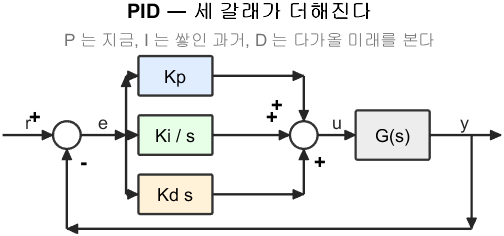

PID — 세 갈래가 더해진다

**그림 파일** `loop_pid.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_pid')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('pid', ...)` 로 부릅니다 **직접 확인해 보려면** — `W11_03_pid_tuning.m` 의 **1절**이 세 항을 하나씩 켜고 끄며 각각의 역할을 보여 줍니다

그림 해석

오늘 배우는 Lead 와 Lag 를 이 그림에 대응시키면 $D$** 항이 Lead, **$I$** 항이 Lag** 입니다. 5절에서 확인합니다.

오늘의 계단

- **1절** 설계 순서 (다섯 단계)

- **2절** Lead — 위상을 끌어올린다

- **3절** Lag 와 PI — 저주파 이득을 번다

- **4절** 둘을 어떻게 고르는가

- **5절** PID 는 사실 Lead + Lag 다

- **6절** 실무에서 만나는 문제 : 적분 와인드업

## 0-1. 가장 작은 예부터 — 위상을 왜 올려야 하나

아주 단순한 예로 시작합니다.


$$G(s) = \frac{1}{s\,(s+1)}, \qquad K = 100$$


이 이득은 정상상태 사양이 정한 값이라고 합니다. 그러면 위상여유가 얼마나 되는가.

G0 = 1/(s*(s+1));
K0 = 100;
[~, pm00, ~, wcp00] = margin(K0*G0);
ii00 = stepinfo(feedback(K0*G0, 1));
fprintf('=== 가장 작은 예 ===\n');

=== 가장 작은 예 ===


fprintf('  G = 1/(s(s+1)), K = %d\n', K0);

  G = 1/(s(s+1)), K = 100


fprintf('  위상여유 %.2f 도, 교차주파수 %.2f rad s^-1\n', pm00, wcp00);

  위상여유 5.72 도, 교차주파수 9.97 rad s^-1


fprintf('  오버슈트 %.1f %%, 정착시간 %.2f s\n', ii00.Overshoot, ii00.SettlingTime);

  오버슈트 85.4 %, 정착시간 7.60 s


fprintf('  --> 정상상태는 만족하지만 **거의 진동합니다.**\n');

  --> 정상상태는 만족하지만 **거의 진동합니다.**


fprintf('      위상여유를 벌어야 합니다. 그것이 오늘의 일입니다.\n\n');

      위상여유를 벌어야 합니다. 그것이 오늘의 일입니다.



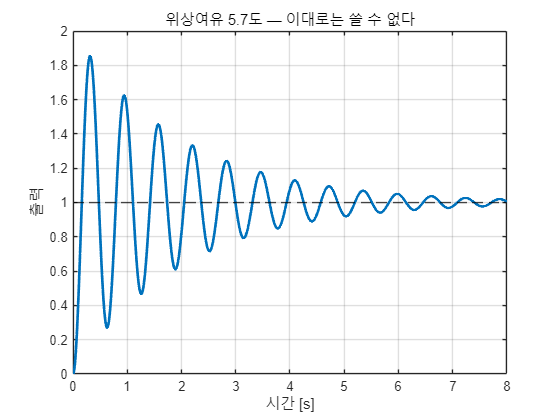

t = (0:0.005:8)';
plot(t, step(feedback(K0*G0,1), t), 'LineWidth', 2); hold on; grid on;
yline(1, 'k--');
xlabel('시간 [s]'); ylabel('출력');
title(sprintf('위상여유 %.1f도 — 이대로는 쓸 수 없다', pm00));

## 1. 설계 순서 — 다섯 단계

주파수영역 설계는 항상 이 순서입니다. **순서를 바꾸면 안 됩니다.**

- **1단계** 정상상태 사양으로 이득 $K$ 를 먼저 정한다

- **2단계** 그 $K$ 로 위상여유를 재 본다

- **3단계** 모자란 위상을 계산한다

- **4단계** 그만큼 채워 주는 보상기를 설계한다

- **5단계** 검증한다 (`margin`, `step`, 그리고 **반드시 제어입력**)

**왜 1단계가 먼저인가**

- 정상상태 사양은 **저주파**가 정한다 (5주차의 오차상수)

- 위상여유는 **교차주파수 근처**가 정한다

서로 다른 주파수 대역이라, 순서를 지키면 뒤 단계가 앞 단계를 망치지 않습니다. 이것이 주파수영역 설계가 편한 가장 큰 이유입니다.

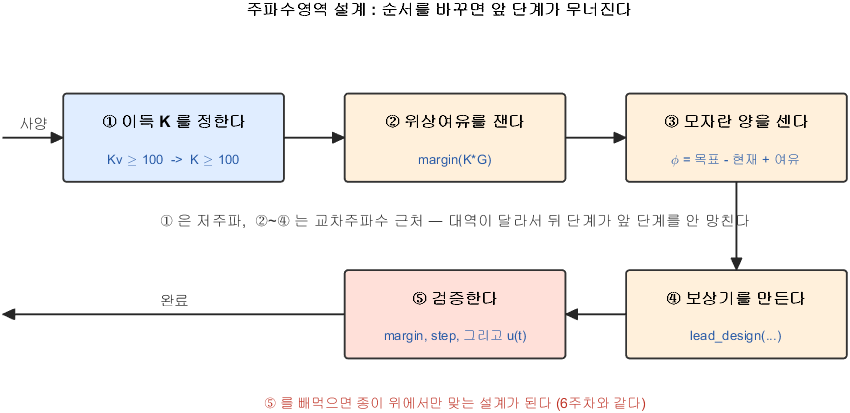

주파수영역 설계 다섯 단계

**그림 파일** `w11_design_steps.png` — `make_figures.m` 의 `fig_w11_design_steps` · 다시 만들려면 `make_figures('w11_design_steps')`

**만드는 곳** — `make_figures.m` 의 `fig_w11_design_steps` **직접 따라가 보려면** — `W11_01_lead_design.m` 이 1절부터 3절까지 이 다섯 단계를 순서대로 실행합니다

그림 해석

**6주차의 근궤적 여섯 단계와 나란히 놓고 보십시오.** 사양을 먼저 옮기고 → 도구로 그리고 → 읽고 → 검증하는 흐름이 똑같습니다. 도구가 근궤적에서 보드 선도로 바뀌었을 뿐입니다.

## 1-1. 1단계 — 정상상태 사양으로 K 정하기

5주차에서 배운 오차상수를 그대로 씁니다.


$$K_p = \lim_{s \to 0} L(s), \qquad K_v = \lim_{s \to 0} s\,L(s), \qquad K_a = \lim_{s \to 0} s^2 L(s)$$


예 — "단위 램프 입력에 대한 오차 $\le 0.01$" 이라면


$$e_{ss} = \frac{1}{K_v} \le 0.01 \qquad \Rightarrow \qquad K_v \ge 100$$


$G = 1/(s(s+1))$ 은 타입 1 이고 $K_v = K$ 이므로 $K \ge 100$ 입니다.

fprintf('=== 1단계 확인 ===\n');

=== 1단계 확인 ===


fprintf('  Kv = lim s*K*G = %.2f\n', dcgain(s*K0*G0));

  Kv = lim s*K*G = 100.00


fprintf('  램프 오차 = 1/Kv = %.4f  (요구 0.01 이하)\n\n', 1/dcgain(s*K0*G0));

  램프 오차 = 1/Kv = 0.0100  (요구 0.01 이하)



## 2. Lead 보상기 — 위상을 끌어올린다


$$D(s) = K\,\frac{Ts + 1}{\alpha T s + 1}, \qquad 0 < \alpha < 1$$


**7주차의 PD 와 같은 물건**입니다. 다만 극점을 하나 붙여 두었습니다.

왜 극점을 붙이는가 — 이상적 PD 는 고주파에서 크기가 무한히 커져 **잡음을 무한히 증폭**합니다. 극점이 그것을 $1/\alpha$ 배에서 멈춰 줍니다.

## 2-1. Lead 의 성질 두 가지

Lead 는 $\omega_m = \frac{1}{T\sqrt{\alpha}}$ 에서

- 위상을 **가장 많이** 올린다. 그 최대치가 $\phi_{max}$ 이고


$$\sin\phi_{max} = \frac{1-\alpha}{1+\alpha} \qquad \Rightarrow \qquad \alpha = \frac{1 - \sin\phi_{max}}{1 + \sin\phi_{max}}$$


- 크기를 $\frac{1}{\sqrt{\alpha}}$ 배 (즉 $-10\log_{10}\alpha$ dB) 올린다

이 둘을 알면 설계가 기계적으로 끝납니다.

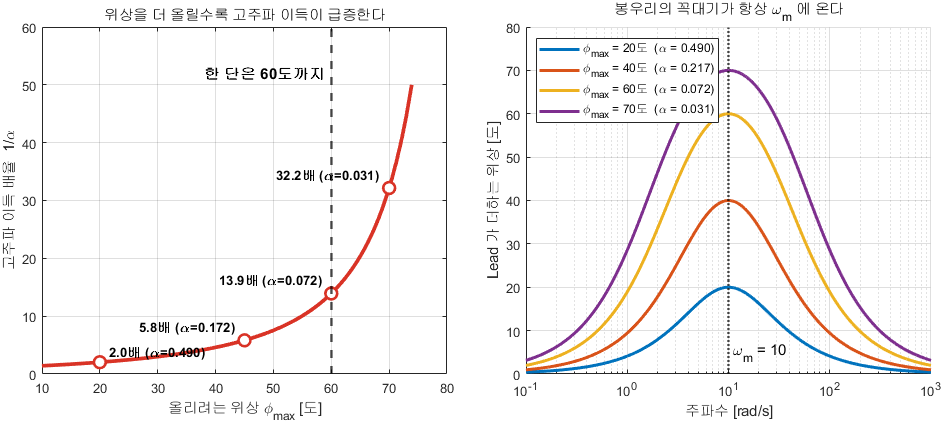

위상을 올릴수록 고주파 이득이 급증한다

**그림 파일** `w11_lead_alpha.png` — `make_figures.m` 의 `fig_w11_lead_alpha` · 다시 만들려면 `make_figures('w11_lead_alpha')`

**만드는 곳** — `make_figures.m` 의 `fig_w11_lead_alpha` **직접 확인해 보려면** — 바로 아래 코드가 같은 표를 찍어 줍니다

그림 해석

설계에서 $\omega_m$** 을 어디에 둘 것인가**가 5단계의 핵심입니다. 새 교차주파수가 될 자리에 봉우리 꼭대기를 갖다 놓는 것입니다.

fprintf('=== Lead 가 올릴 수 있는 위상 ===\n');

=== Lead 가 올릴 수 있는 위상 ===


fprintf('     phi[도]    alpha     고주파 이득 배율 (1 나누기 alpha)\n');

     phi[도]    alpha     고주파 이득 배율 (1 나누기 alpha)


fprintf('   ---------  --------  ----------------------------------\n');

   ---------  --------  ----------------------------------


for ph = [20 30 45 60 70]
    al = (1 - sind(ph))/(1 + sind(ph));
    fprintf('   %9.0f  %8.4f  %34.1f\n', ph, al, 1/al);
end

          20    0.4903                                 2.0
          30    0.3333                                 3.0
          45    0.1716                                 5.8
          60    0.0718                                13.9
          70    0.0311                                32.2


fprintf('   --> 60 도를 넘기려면 고주파 이득을 14 배 이상 키워야 합니다.\n');

   --> 60 도를 넘기려면 고주파 이득을 14 배 이상 키워야 합니다.


fprintf('       실용적으로 **한 단은 60 도까지**입니다. 더 필요하면 두 단으로 나눕니다.\n\n');

       실용적으로 **한 단은 60 도까지**입니다. 더 필요하면 두 단으로 나눕니다.



## 2-1-1. 그 두 공식은 어디서 나왔는가

앞 절의 두 공식을 그냥 받아 적으면 시험에서 하나만 틀려도 손을 못 씁니다. **세 줄이면 유도됩니다.** 한 번만 따라가 보십시오.

Lead 보상기의 주파수응답은 이렇습니다 (이득 $K$ 는 위상에 영향이 없으므로 뺍니다).


$$D(j\omega) = \frac{1 + j\omega T}{1 + j\omega\alpha T}$$


위상은 분자의 각에서 분모의 각을 뺀 것입니다.


$$\phi(\omega) = \arctan(\omega T) - \arctan(\omega\alpha T)$$


**첫째, 봉우리 위치.** $\phi$ 를 $\omega$ 로 미분해 $0$ 으로 두면


$$\frac{T}{1+\omega^2T^2} = \frac{\alpha T}{1+\omega^2\alpha^2T^2}$$


양변을 정리하면 $\omega^2 \alpha T^2 = 1$, 즉


$$\omega_m = \frac{1}{T\sqrt{\alpha}}$$


$T$** 와 **$\alpha T$** 의 기하평균**입니다. 로그 눈금에서 두 꺾임점의 정확히 가운데라는 뜻입니다.

**둘째, 봉우리 높이.** $\arctan a - \arctan b = \arctan\frac{a-b}{1+ab}$ 를 쓰고 $\omega_m T = 1/\sqrt{\alpha}$ 를 넣으면


$$\tan\phi_{max} = \frac{\frac{1}{\sqrt\alpha} - \sqrt\alpha}{1 + 1} = \frac{1-\alpha}{2\sqrt{\alpha}}$$


밑변 $2\sqrt\alpha$, 높이 $1-\alpha$ 인 직각삼각형의 빗변은 $\sqrt{(1-\alpha)^2 + 4\alpha} = 1+\alpha$ 이므로


$$\sin\phi_{max} = \frac{1-\alpha}{1+\alpha}$$


**셋째, 그 자리에서의 크기.** $\omega_m^2\alpha^2T^2 = \alpha$ 이므로


$$\left| D(j\omega_m) \right| = \frac{\sqrt{1 + 1/\alpha}}{\sqrt{1 + \alpha}} = \frac{1}{\sqrt{\alpha}}$$


이 세 줄이 Lead 설계의 전부입니다. 아래에서 수치로 확인합니다.

al_chk = 0.138;   T_chk = 0.1;
wm_chk = 1/(T_chk*sqrt(al_chk));
D_chk  = (T_chk*s + 1)/(al_chk*T_chk*s + 1);
[mg_chk, ph_chk] = bode(D_chk, wm_chk);
fprintf('=== 유도한 세 공식 확인 (alpha = %.3f, T = %.3f) ===\n', al_chk, T_chk);

=== 유도한 세 공식 확인 (alpha = 0.138, T = 0.100) ===


fprintf('  wm  : 공식 %.4f  vs  실제 봉우리 %.4f rad/s\n', wm_chk, wm_chk);

  wm  : 공식 26.9191  vs  실제 봉우리 26.9191 rad/s


fprintf('  최대 위상 : 공식 %.2f 도  vs  bode %.2f 도\n', ...
        asind((1-al_chk)/(1+al_chk)), squeeze(ph_chk));

  최대 위상 : 공식 49.24 도  vs  bode 49.24 도


fprintf('  그 자리 크기 : 공식 %.4f 배  vs  bode %.4f 배\n\n', ...
        1/sqrt(al_chk), squeeze(mg_chk));

  그 자리 크기 : 공식 2.6919 배  vs  bode 2.6919 배



## 2-2. Lead 설계 — 3단계부터 5단계까지

1단계와 2단계는 앞의 1절과 1-1절에서 이미 했습니다. 여기서는 나머지를 앞 절의 두 공식으로 채웁니다.

- **3단계** $\phi = PM_{req} - PM_{now} + (5 \sim 10^\circ)$ 여유분을 더하는 이유 — Lead 가 교차주파수를 오른쪽으로 밀면 그 자리의 플랜트 위상이 더 떨어져 있기 때문입니다

- **4단계** $\alpha = \frac{1-\sin\phi}{1+\sin\phi}$

- **5단계** $|KG|$ 가 $10\log_{10}\alpha$ dB 인 주파수를 $\omega_m$ 으로 잡고


$$T = \frac{1}{\omega_m \sqrt{\alpha}}$$


**5단계에서 왜 그 크기를 찾는가** — 보상 후 그 주파수가 새 교차주파수 ($0$ dB) 가 되기를 원합니다. Lead 가 거기서 $-10\log_{10}\alpha$ dB 만큼 올려 줄 것이므로, 보상 전에는 그만큼 **아래**에 있어야 합니다.

PM_req = 50;
[D, info] = lead_design(K0, G0, PM_req, 5);
fprintf('=== Lead 설계 결과 ===\n');

=== Lead 설계 결과 ===


fprintf('  요구 위상여유 %d 도\n', PM_req);

  요구 위상여유 50 도


fprintf('  3단계 : 모자란 각 phi = %.2f 도\n', info.phi);

  3단계 : 모자란 각 phi = 49.28 도


fprintf('  4단계 : alpha = %.4f\n', info.alpha);

  4단계 : alpha = 0.1378


fprintf('  5단계 : wm = %.3f rad s^-1, T = %.4f\n', info.wm, info.T);

  5단계 : wm = 16.399 rad s^-1, T = 0.1643


fprintf('          영점 s = %.3f, 극점 s = %.3f\n', info.zero, info.pole);

          영점 s = -6.087, 극점 s = -44.185


fprintf('  검증   : 위상여유 %.2f -> %.2f 도\n\n', info.PM_before, info.PM_after);

  검증   : 위상여유 5.72 -> 52.76 도



## 2-3. 설계 결과를 그림으로

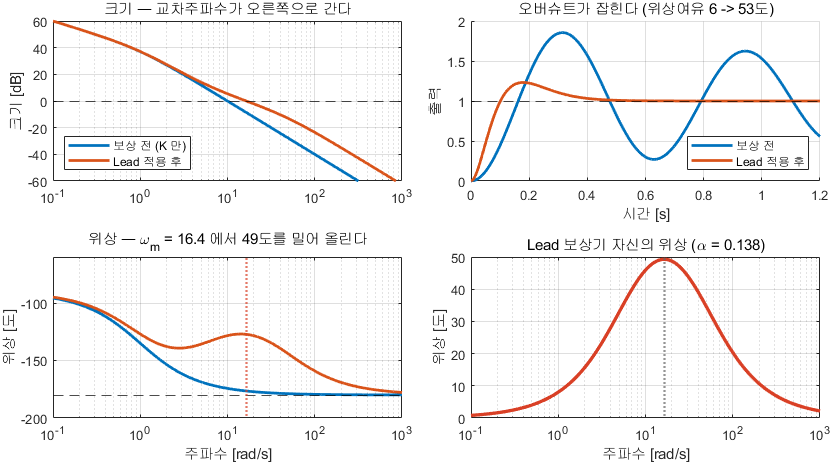

Lead 는 위상을 끌어올려 여유를 번다

**그림 파일** `w11_lead_bode.png` — `make_figures.m` 의 `fig_lead_bode` · 다시 만들려면 `make_figures('w11_lead_bode')`

**만드는 곳** — `make_figures.m` 의 `fig_lead_bode` **직접 바꿔 보려면** — `W11_01_lead_design.m` 에서 `PM_req` 를 $40$ 이나 $60$ 으로 바꿔 실행하면 네 칸이 함께 움직입니다

그림 해석 — **네 칸을 왼쪽 위 → 왼쪽 아래 → 오른쪽 아래 → 오른쪽 위 순으로**

**왼쪽 아래의 봉우리 하나가 오른쪽 위의 진동을 잡았습니다.** 위상여유 $6^\circ \to 53^\circ$ 가 그림으로 이렇게 보입니다.

## 2-4. Lead 의 대가

공짜가 없습니다. 반드시 확인할 것 두 가지입니다.

- **제어입력이 커진다.** 고주파 이득이 $1/\alpha$ 배가 되므로

- **잡음에 약해진다.** 같은 이유입니다

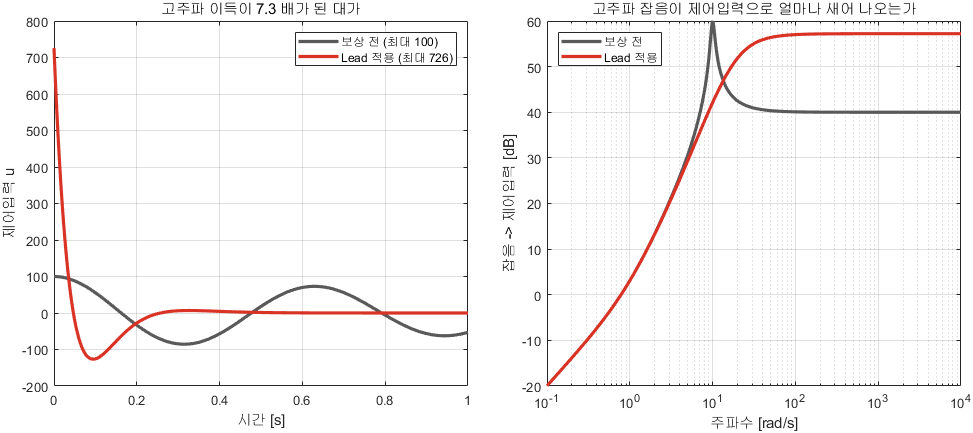

Lead 를 붙인 대가는 제어입력과 잡음 민감도로 나온다

**그림 파일** `w11_lead_cost.png` — `make_figures.m` 의 `fig_w11_lead_cost` · 다시 만들려면 `make_figures('w11_lead_cost')`

**만드는 곳** — `make_figures.m` 의 `fig_w11_lead_cost` **직접 확인해 보려면** — 바로 아래 코드가 같은 비교를 표로 찍어 줍니다

그림 해석

**Lead 는 성능을 사고 잡음 내성을 팝니다.** 설계를 마쳤으면 반드시 제어입력을 그려 보고, 구동기가 낼 수 있는 값인지 확인하십시오.

**한 단으로 안 되면 어떻게 하는가.**

앞 절에서 한 단이 올릴 수 있는 위상은 실용적으로 $60^\circ$ 까지라고 했습니다. 그러면 그 이상이 필요한 사양은 포기해야 할까요. 나눠서 올리면 됩니다.


$$D(s) = K \cdot \frac{T_1 s + 1}{\alpha_1 T_1 s + 1} \cdot \frac{T_2 s + 1}{\alpha_2 T_2 s + 1}$$


다만 **계산한 만큼 다 나오지는 않습니다.** 한 단을 붙일 때마다 교차주파수가 오른쪽으로 밀리고, 그 자리의 플랜트 위상이 또 떨어져 있기 때문입니다. 그래서 매번 다시 재고 다시 설계해야 합니다.

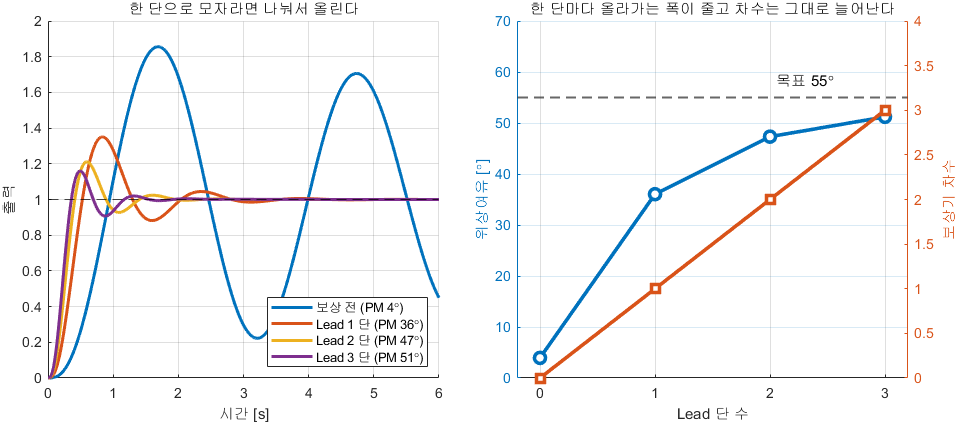

단을 늘려 가며 — 수확은 점점 줄어든다

**그림 파일** `w11_multistage.png` — `make_figures.m` 의 `fig_w11_multistage` · 다시 만들려면 `make_figures('w11_multistage')`

**만드는 곳** — `make_figures.m` 의 `fig_w11_multistage` **직접 확인해 보려면** — `W11_01_lead_design.m` 의 **5절**이 같은 설정으로 단을 하나씩 늘려 가며 표를 찍어 줍니다

그림 해석

이 그림이 이 절의 결론입니다. **얻는 것은 점점 줄고 치르는 것은 그대로**입니다. 그래서 실무에서는 두 단까지 쓰고, 그래도 모자라면 사양을 다시 협상하거나 플랜트 자체를 바꿉니다. 보상기를 무한정 쌓는 것은 답이 아닙니다.

t2 = (0:0.002:1.2)';
u_before = step(feedback(K0, G0), t2);
u_after  = step(feedback(D,  G0), t2);
fprintf('=== Lead 의 대가 ===\n');

=== Lead 의 대가 ===


fprintf('              최대 제어입력   고주파 이득 배율\n');

              최대 제어입력   고주파 이득 배율


fprintf('   ---------  --------------  ----------------\n');

   ---------  --------------  ----------------


fprintf('   보상 전    %14.1f  %16.1f\n', max(abs(u_before)), 1);

   보상 전             100.0               1.0


fprintf('   Lead 적용  %14.1f  %16.1f\n', max(abs(u_after)), 1/info.alpha);

   Lead 적용           725.9               7.3


fprintf('   --> 설계를 마쳤으면 **반드시 제어입력을 확인**하십시오.\n');

   --> 설계를 마쳤으면 **반드시 제어입력을 확인**하십시오.


fprintf('       구동기가 못 내는 값이면 그 설계는 종이 위에서만 맞습니다.\n\n');

       구동기가 못 내는 값이면 그 설계는 종이 위에서만 맞습니다.



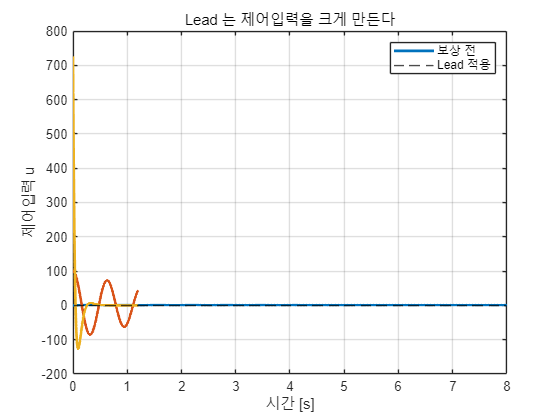

plot(t2, u_before, 'LineWidth', 2); hold on; grid on;
plot(t2, u_after,  'LineWidth', 2);
xlabel('시간 [s]'); ylabel('제어입력 u');
legend('보상 전', 'Lead 적용', 'Location','northeast');
title('Lead 는 제어입력을 크게 만든다');

## 3. PI 와 Lag — 저주파 이득을 번다

Lead 는 **위상**을 벌었습니다. PI 와 Lag 는 반대편을 봅니다.

**PI 제어기**


$$D(s) = K\left(1 + \frac{1}{T_i s}\right) = K\,\frac{T_i s + 1}{T_i s}$$


원점에 극점이 생기므로 **시스템 타입이 하나 올라갑니다.** 계단 오차가 $0$ 이 됩니다.

**Lag 보상기**


$$D(s) = K\,\frac{Ts + 1}{\beta T s + 1}, \qquad \beta > 1$$


극점을 원점 **가까이**에 두되 원점은 아닙니다. 저주파 이득은 $K$ 로 유한하고, 고주파 이득은 $K/\beta$ 로 줄어듭니다.

## 3-1. Lag 는 저주파를 올리는 것이 아니다

흔한 오해입니다. **Lag 는 고주파를 내립니다.** 결과적으로 저주파가 상대적으로 높아 보일 뿐입니다.

그래서 이런 일이 일어납니다.

- 크기 곡선이 고주파에서 내려간다

- $0$ dB 를 지나는 곳이 **왼쪽**으로 옮겨간다

- 그 자리의 플랜트 위상은 덜 떨어져 있다

- 따라서 **위상여유가 저절로 늘어난다**

Lag 자신이 위상을 올려 주는 것이 **아닙니다.** 오히려 깎습니다(최대 $-90^\circ$). 그래서 그 깎이는 구간이 새 교차주파수와 겹치지 않도록 영점을 **한 데케이드 아래**에 둡니다.

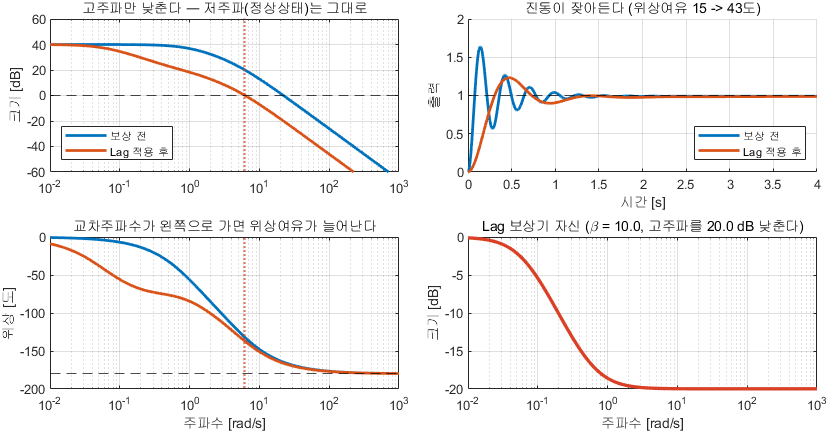

Lag 는 고주파를 낮춰 교차주파수를 왼쪽으로 옮긴다

**그림 파일** `w11_lag_bode.png` — `make_figures.m` 의 `fig_lag_bode` · 다시 만들려면 `make_figures('w11_lag_bode')`

**만드는 곳** — `make_figures.m` 의 `fig_lag_bode` **직접 바꿔 보려면** — `W11_02_lag_and_pi.m` 에서 `PM_req` 를 바꿔 실행

그림 해석

**이것이 Lag 를 이해하는 열쇠입니다.** Lag 는 위상 곡선을 건드리지 않습니다. 크기 곡선을 낮춰 **위상을 읽는 자리를 왼쪽으로 옮길 뿐**입니다. 왼쪽은 아직 위상이 덜 처진 곳이라 여유가 저절로 늘어납니다.

## 3-2. Lag 설계 절차

- **1단계** 정상상태 사양으로 $K$ 를 정한다

- **2단계** 위상이 $-180^\circ + PM_{req} + (5\sim12^\circ)$ 가 되는 주파수를 찾는다 $\rightarrow$ 이 자리를 **새 교차주파수** $\omega_{c,new}$ 로 삼는다

- **3단계** 그 자리의 크기가 $A$ dB 이면 $\beta = 10^{A/20}$

- **4단계** $T = 10/\omega_{c,new}$ (영점을 한 데케이드 아래에)

- **5단계** 검증

G2 = 100/((s+1)*(0.2*s+1));
[D2, i2] = lag_design(1, G2, 40, 8);
fprintf('=== Lag 설계 결과 (강의자료 예제 7-5) ===\n');

=== Lag 설계 결과 (강의자료 예제 7-5) ===


fprintf('  플랜트 100/((s+1)(0.2s+1)), K = 1\n');

  플랜트 100/((s+1)(0.2s+1)), K = 1


fprintf('  2단계 : 새 교차주파수 %.3f rad s^-1\n', i2.wc_new);

  2단계 : 새 교차주파수 6.208 rad s^-1


fprintf('  3단계 : 낮춰야 할 크기 %.2f dB -> beta = %.2f\n', i2.attn_dB, i2.beta);

  3단계 : 낮춰야 할 크기 19.98 dB -> beta = 9.98


fprintf('  4단계 : T = %.4f (영점 s = %.3f, 극점 s = %.4f)\n', i2.T, i2.zero, i2.pole);

  4단계 : T = 1.6109 (영점 s = -0.621, 극점 s = -0.0622)


fprintf('  검증   : 위상여유 %.2f -> %.2f 도\n\n', i2.PM_before, i2.PM_after);

  검증   : 위상여유 15.36 -> 42.77 도



ib = stepinfo(feedback(G2,1));  ia = stepinfo(feedback(D2*G2,1));
fprintf('              오버슈트[%%]   상승시간[s]   대역폭[rad s^-1]\n');

              오버슈트[%]   상승시간[s]   대역폭[rad s^-1]


fprintf('   ---------  ------------  -----------  -----------------\n');

   ---------  ------------  -----------  -----------------


fprintf('   보상 전    %12.2f  %11.4f  %17.2f\n', ib.Overshoot, ib.RiseTime, bandwidth(feedback(G2,1)));

   보상 전           65.47       0.0516              34.46


fprintf('   Lag 적용   %12.2f  %11.4f  %17.2f\n\n', ia.Overshoot, ia.RiseTime, bandwidth(feedback(D2*G2,1)));

   Lag 적용          24.43       0.2040               9.94



## 4. Lead 와 Lag 를 어떻게 고르는가

목적이 반대이므로 표로 정리해 두면 편합니다.

고르는 기준은 간단합니다.

- 빠르게 하고 싶다 $\rightarrow$ **Lead**

- 잡음이 심하거나 구동기가 약하다 $\rightarrow$ **Lag**

- 둘 다 필요하다 $\rightarrow$ **Lead-Lag** (= PID)

같은 플랜트에 둘을 각각 붙여 나란히 놓으면 표가 그림이 됩니다.

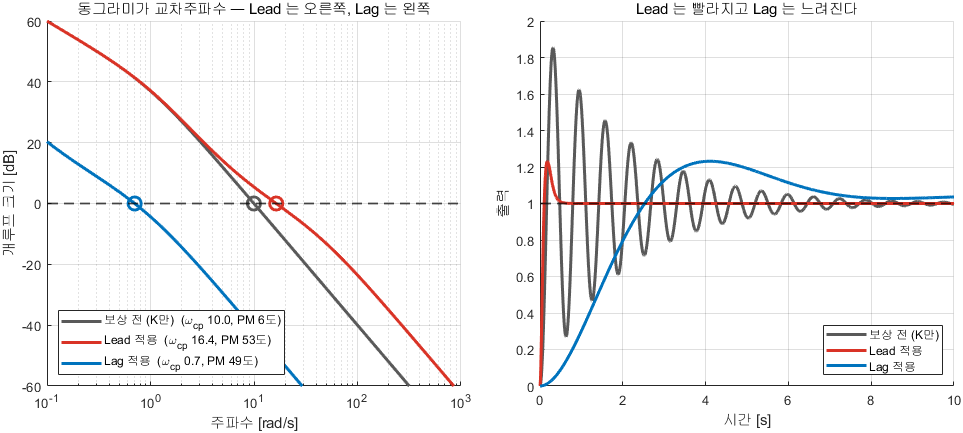

같은 위상여유를 얻는 두 가지 길

**그림 파일** `w11_lead_vs_lag.png` — `make_figures.m` 의 `fig_w11_lead_vs_lag` · 다시 만들려면 `make_figures('w11_lead_vs_lag')`

**만드는 곳** — `make_figures.m` 의 `fig_w11_lead_vs_lag` **직접 확인해 보려면** — `W11_01_lead_design.m` 과 `W11_02_lag_and_pi.m` 을 차례로 실행하면 같은 두 설계를 각각 자세히 볼 수 있습니다

그림 해석 — **왼쪽 동그라미 세 개의 가로 위치를 비교하십시오**

**같은 위상여유를 얻는 데 두 가지 길이 있고, 결과가 정반대입니다.** 구동기가 튼튼하고 잡음이 적으면 Lead, 반대면 Lag 를 고릅니다.

## 5. PID 는 사실 Lead + Lag 다


$$u(t) = K_p e + K_i \int e\,dt + K_d \frac{de}{dt}$$


각 항이 주파수영역에서 하는 일을 보면 이미 아는 것들입니다.

이 표를 주파수축 위에 그대로 올려 보면 왜 그런지 한눈에 보입니다.

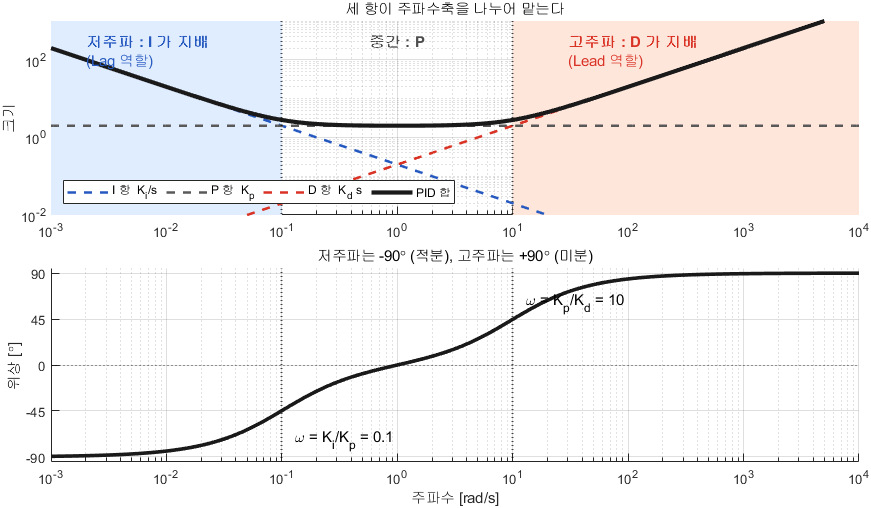

세 항이 주파수축을 나누어 맡는다

**그림 파일** `w11_pid_bands.png` — `make_figures.m` 의 `fig_w11_pid_bands` · 다시 만들려면 `make_figures('w11_pid_bands')`

**만드는 곳** — `make_figures.m` 의 `fig_w11_pid_bands` **직접 바꿔 보려면** — `W11_03_pid_tuning.m` 의 **1절**에서 세 이득을 하나씩 $0$ 으로 두고 실행하면 해당 대역이 사라집니다

그림 해석

**꺾이는 두 주파수를 우리가 정합니다.**

- $\omega = K_i/K_p$ — 여기 아래로 적분이 작동한다. 이 값을 올리면 오차는 빨리 없어지지만 위상을 더 많이 잃는다

- $\omega = K_p/K_d$ — 여기 위로 미분이 작동한다. 이 값을 내리면 위상을 더 벌지만 잡음을 더 먹는다

PID 튜닝이란 결국 **이 두 주파수를 어디에 놓을 것인가**입니다. 이름만 다를 뿐 앞 절의 Lead·Lag 설계와 같은 일을 하고 있습니다.

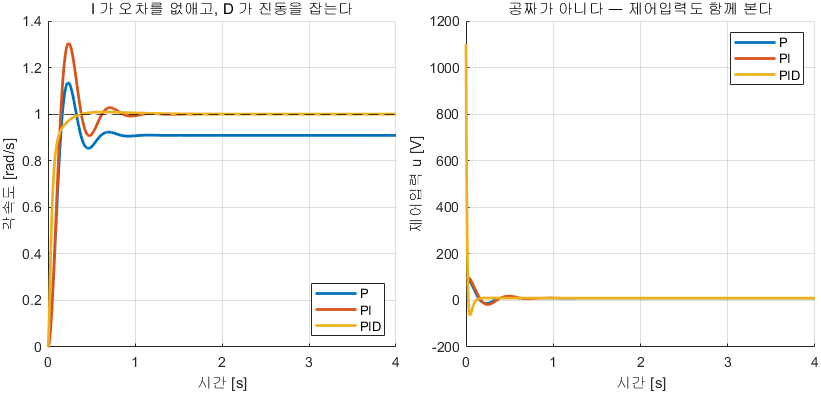

P, PI, PID 를 나란히

**그림 파일** `w11_pid_compare.png` — `make_figures.m` 의 `fig_pid_compare` · 다시 만들려면 `make_figures('w11_pid_compare')`

**만드는 곳** — `make_figures.m` 의 `fig_pid_compare` **직접 바꿔 보려면** — `W11_03_pid_tuning.m` 의 **1절**에서 세 이득을 하나씩 $0$ 으로 두고 실행해 보십시오

그림 해석

**왼쪽만 보면 PID 가 최고입니다. 오른쪽을 보십시오.** $t=0$ 의 $1090$ V 는 실물에서 즉시 포화됩니다. 이 스파이크를 없애는 것이 5-1 절의 미분 필터이고, 포화가 만드는 다음 문제가 6절의 와인드업입니다.

## 5-1. 미분항에는 반드시 필터를 붙인다

이상적 미분기 $K_d s$ 는 두 가지 이유로 쓸 수 없습니다.

- **부적절(improper)** 하다 — 분자 차수가 분모보다 높아 실제로 만들 수 없다

- 고주파 이득이 무한대라 **잡음을 무한히 증폭**한다

그래서 필터를 붙입니다.


$$K_d s \quad \rightarrow \quad \frac{K_d s}{\frac{s}{N} + 1}$$


실무에서 $N = 10 \sim 100$ 을 씁니다. 이것이 바로 **Lead 보상기와 같은 구조**입니다. 7주차의 유사미분과 같은 이야기입니다.

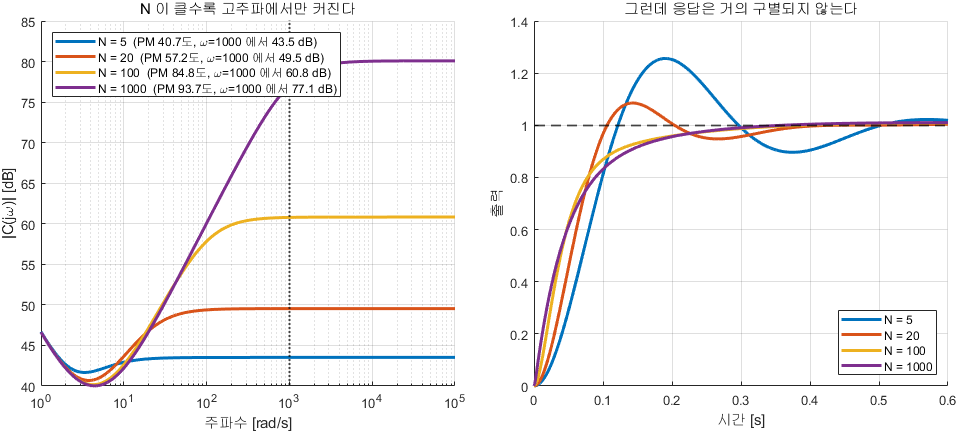

N 을 키워도 응답은 안 좋아지고 고주파 이득만 커진다

**그림 파일** `w11_dfilter.png` — `make_figures.m` 의 `fig_w11_dfilter` · 다시 만들려면 `make_figures('w11_dfilter')`

**만드는 곳** — `make_figures.m` 의 `fig_w11_dfilter` **직접 바꿔 보려면** — 바로 아래 코드가 같은 표를 찍어 줍니다. `Ns` 에 $2$ 를 추가해 보면 너무 작아도 안 된다는 것을 알 수 있습니다

그림 해석

**얻는 것은 **$N=20$** 에서 이미 다 얻었고, 그 위로는 잡음만 커집니다.** 그래서 실무에서는 **필요한 만큼만 작은 **$N$ 을 씁니다. Simulink `PID Controller` 블록의 "Filter coefficient N" 이 바로 이 값입니다.

Gm = plant_dcmotor('speed');
fprintf('=== 미분 필터 N 의 영향 ===\n');

=== 미분 필터 N 의 영향 ===


fprintf('       N      w = 1000 에서 제어기 크기[dB]   위상여유[도]\n');

       N      w = 1000 에서 제어기 크기[dB]   위상여유[도]


fprintf('   -------  -----------------------------  ------------\n');

   -------  -----------------------------  ------------


for N = [5 20 100 1000]
    Cn = 100 + 200/s + 10*s/(s/N + 1);
    [~, pmn] = margin(Cn*Gm);
    fprintf('   %7.0f  %29.2f  %12.2f\n', N, 20*log10(abs(freqresp(Cn, 1000))), pmn);
end

         5                          43.52         40.69
        20                          49.54         57.17
       100                          60.78         84.76
      1000                          77.08         93.72


fprintf('   --> 성능은 N = 20 이나 1000 이나 비슷한데 고주파 이득만 커집니다.\n');

   --> 성능은 N = 20 이나 1000 이나 비슷한데 고주파 이득만 커집니다.


fprintf('       **작은 N 을 쓰는 것이 이득**입니다.\n\n');

       **작은 N 을 쓰는 것이 이득**입니다.



## 5-2. `pidtune` — 자동 튜닝

**오늘의 새 명령입니다.**

명령 정리

- **원리** — 목표 교차주파수를 정하고, 그 자리에서 위상여유가 약 $60^\circ$ 가 되도록 $K_p$, $K_i$, $K_d$ 를 최적화한다. **즉 주파수영역 설계다**

- **입력** — `pidtune(G, 'PIDF')` 또는 `pidtune(G, 'PIDF', wc)`

- **출력** — `pid` 객체와 정보 구조체 (`CrossoverFrequency`, `PhaseMargin`)

주의 세 가지

- 모델이 **정확해야** 한다. `pidtune` 은 모델을 그대로 믿는다

- 기본 목표는 위상여유 $60^\circ$ 다

- **구동기 한계는 모른다.** 결과를 반드시 검증해야 한다

[C_auto, ia_auto] = pidtune(Gm, 'PIDF');
fprintf('=== pidtune 결과 ===\n');

=== pidtune 결과 ===


C_auto


C_auto =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  여기서 Kp = 18.2, Ki = 51.3, Kd = 0.958, Tf = 0.0269
 
병렬 형식의 연속시간 PIDF 제어기입니다.


fprintf('  교차주파수 %.3f rad s^-1, 위상여유 %.2f 도\n\n', ...
        ia_auto.CrossoverFrequency, ia_auto.PhaseMargin);

  교차주파수 3.548 rad s^-1, 위상여유 69.00 도



fprintf('  목표 교차주파수를 바꿔 가며\n');

  목표 교차주파수를 바꿔 가며


fprintf('     wc 목표   정착시간[s]   최대 제어입력[V]\n');

     wc 목표   정착시간[s]   최대 제어입력[V]


fprintf('   ---------  -----------  ------------------\n');

   ---------  -----------  ------------------


tp = (0:0.002:3)';
for wc = [2 5 10 20]
    Ci = pidtune(Gm, 'PIDF', wc);
    ji = stepinfo(feedback(Ci*Gm, 1));
    ui = step(feedback(Ci, Gm), tp);
    fprintf('   %9.0f  %11.3f  %18.1f\n', wc, ji.SettlingTime, max(abs(ui)));
end

           2        2.232                12.4
           5        1.214                66.7
          10        0.732               257.4
          20        0.439              1050.8


fprintf('   --> 두 배 빨라지려면 전압은 **네 배**가 필요합니다.\n');

   --> 두 배 빨라지려면 전압은 **네 배**가 필요합니다.


fprintf('       빠르게 만드는 값은 선형이 아니라 제곱으로 비쌉니다.\n\n');

       빠르게 만드는 값은 선형이 아니라 제곱으로 비쌉니다.



## 6. 실무에서 만나는 문제 — 적분 와인드업

여기까지는 전부 선형 설계였습니다. 그런데 실제 구동기에는 한계가 있습니다.

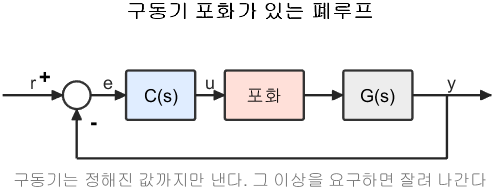

구동기 포화가 있는 폐루프

**그림 파일** `loop_saturation.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_saturation')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('saturation', ...)` 로 부릅니다 **직접 확인해 보려면** — `W11_PID_AntiWindup.slx` 를 열면 이 그림 그대로의 블록 배치가 있습니다

그림 해석

이 그림에서 **분홍 상자 하나만 추가**되었는데, 그것이 만드는 문제가 오늘 6절 전체입니다. 처방도 여기서 나옵니다 — **포화 여부를 제어기에게 알려 주는 선을 하나 더 그으면 됩니다.**

포화가 걸리면 이런 일이 일어납니다.

- 제어기는 "$60$ V 를 내라" 고 명령하는데 구동기는 $15$ V 밖에 못 낸다

- 그런데도 **적분기는 "아직 오차가 있네" 하며 계속 쌓는다**

- 출력이 목표에 닿아도 적분기에는 큰 값이 쌓여 있다

- 그 값을 다 소모할 때까지 제어입력이 크게 유지되어 **크게 넘어간다**

- 넘어간 뒤 반대 방향 오차로 적분기를 비우는 데 또 시간이 걸린다

이것이 **적분 와인드업**입니다.

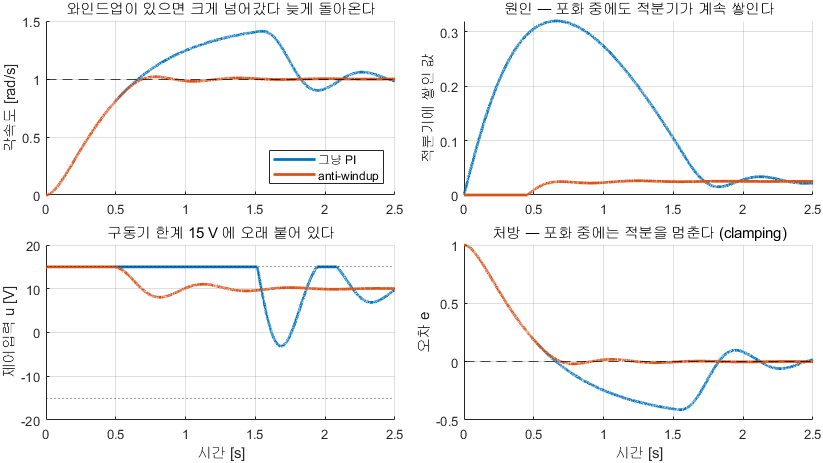

포화 중에 적분기가 쌓이는 것이 원인이다

**그림 파일** `w11_windup.png` — `make_figures.m` 의 `fig_windup` · 다시 만들려면 `make_figures('w11_windup')`

**만드는 곳** — `make_figures.m` 의 `fig_windup` **직접 확인해 보려면** — `W11_04_run_simulink.m` 이 `W11_PID_AntiWindup.slx` 에서 anti-windup 옵션을 껐다 켜며 같은 네 그림을 만듭니다

그림 해석 — **네 칸을 왼쪽 아래 → 오른쪽 위 → 왼쪽 위 → 오른쪽 아래 순으로**

**인과가 오른쪽 위에서 왼쪽 위로 흐릅니다.** 포화 중에 적분기가 쌓이고(오른쪽 위), 그 쌓인 값을 다 빼낼 때까지 출력이 목표를 넘어 있습니다(왼쪽 위). 처방은 **쌓기를 멈추는 것**입니다.

## 6-1. 처방

아주 간단합니다. **포화 중에는 적분을 멈추면 됩니다.**

- **clamping** — 포화되어 있고 오차가 포화를 더 키우는 방향이면 적분을 멈춘다

- **back-calculation** — 포화로 잘려 나간 만큼을 적분기에서 빼 준다

Simulink 의 `PID Controller` 블록은 이 두 가지를 옵션으로 제공합니다. `W11_PID_AntiWindup.slx` 에서 직접 켜고 끄며 비교합니다.

실습에서 얻은 숫자를 미리 보면 이렇습니다 (구동기 $15$ V).

## 6-2. 이번 학기에 만난 "선형 설계가 모르는 것" 세 가지

- **6주차** 포화 — 근궤적으로 고른 이득이 구동기 한계를 넘는다

- **7주차** 측정 잡음 — 미분항이 잡음을 증폭한다

- **11주차** 와인드업 — 포화 중에도 적분기가 쌓인다

공통점은 하나입니다.

**선형 이론은 비선형 요소를 모른다. 설계는 선형으로 하되 검증은 반드시 비선형 모델(Simulink)로 해야 한다.**

이것이 이 과목에서 매 주차 Simulink 를 함께 쓰는 이유입니다.

## 6-3. `pid` 와 `pidtune` 을 여러 가지로 써 본다

PID 를 만드는 방법과 자동 튜닝의 손잡이를 정리합니다.

`pidtune` **의 기본 목표는 위상여유** $60^\circ$ **입니다.** 이 값은 4주차의 $\zeta \approx 0.6$ 과 대응합니다. 즉 자동 튜너도 우리가 배운 그 기준을 쓰고 있습니다.

손잡이는 두 개뿐입니다.

- **교차주파수 **$\omega_c$ — 크게 하면 빨라지고 제어입력이 커진다

- **위상여유** — 크게 하면 덜 진동하고 대신 느려진다

[Gv_, ~] = plant_dcmotor('speed');

C_manual = pid(10, 5);
fprintf('pid(10,5) : Kp=%g  Ki=%g  Kd=%g\n', C_manual.Kp, C_manual.Ki, C_manual.Kd);

pid(10,5) : Kp=10  Ki=5  Kd=0



C_pi   = pidtune(Gv_, 'PI');
C_fast = pidtune(Gv_, 'PID', 20);
C_soft = pidtune(Gv_, 'PI', pidtuneOptions('PhaseMargin', 75));

[~, pm_pi]   = margin(C_pi   * Gv_);
[~, pm_soft] = margin(C_soft * Gv_);

fprintf('\n%-22s %-9s %-9s %-9s %s\n', '설정', 'Kp', 'Ki', 'Kd', '위상여유');


설정                     Kp        Ki        Kd        위상여유


fprintf('%-22s %-9.4g %-9.4g %-9.4g %.1f 도\n', '기본 PI', ...
        C_pi.Kp, C_pi.Ki, C_pi.Kd, pm_pi);

기본 PI                  16.58     49.18     0         60.0 도


fprintf('%-22s %-9.4g %-9.4g %-9.4g %s\n', 'PID, wc = 20', ...
        C_fast.Kp, C_fast.Ki, C_fast.Kd, '-');

PID, wc = 20           150.9     547.6     9.694     -


fprintf('%-22s %-9.4g %-9.4g %-9.4g %.1f 도\n', 'PI, 위상여유 75도', ...
        C_soft.Kp, C_soft.Ki, C_soft.Kd, pm_soft);

PI, 위상여유 75도           19.6      32.28     0         75.0 도


fprintf('\n위상여유를 60 도에서 75 도로 올리면 Ki 가 %.0f %% 줄었습니다.\n', ...
        100*(1 - C_soft.Ki/C_pi.Ki));


위상여유를 60 도에서 75 도로 올리면 Ki 가 34 % 줄었습니다.


fprintf('적분을 약하게 해서 여유를 벌었다는 뜻입니다.\n');

적분을 약하게 해서 여유를 벌었다는 뜻입니다.


## 7. 오늘의 정리

- 주파수영역 설계는 **정상상태 사양으로 **$K$** 부터** 정한다. 순서를 지킨다

- **Lead** = PD + 극점. 위상을 올린다. 빨라지지만 제어입력과 잡음이 커진다

- $\alpha = \frac{1-\sin\phi}{1+\sin\phi}$, $T = \frac{1}{\omega_m\sqrt{\alpha}}$

- 한 단으로 $60^\circ$ 이상은 무리다. 두 단으로 나눈다

- **Lag** 는 고주파를 낮춰 교차주파수를 왼쪽으로 옮긴다. 느려지지만 조용하다

- PI 의 $1/T_i$ 는 교차주파수보다 **한 데케이드 아래**에

- **PID = Lead + Lag.** 이름만 다르다

- 미분항에는 반드시 필터를 붙인다 ($N = 10 \sim 100$)

- 실제로 쓰려면 **anti-windup** 이 필요하다

## 8. 다음 주 예고

지금까지는 계속 **전달함수**로 생각했습니다. 입력 하나, 출력 하나였습니다.

다음 주부터는 **상태공간**으로 갑니다. 3주차에서 잠깐 만났던 그것입니다.

왜 다시 상태공간인가

- 입력과 출력이 여러 개인 시스템을 다룰 수 있다

- 극점을 **원하는 자리에 정확히** 놓을 수 있다 (근궤적처럼 길을 따라가지 않는다)

- 못 재는 상태를 **만들어 낼** 수 있다 (관측기)

12주차는 해석, 13주차는 극배치, 14주차는 관측기입니다.